disp('SCARA_V3')

SCARA_V3


syms a1 a2 a3 a4

a1 = 20;
a2 = 30;
a3 = 10;
a4 = 15;

H0_1 = Link([0,0,0,0,1,a1]);
H0_1.qlim = [0 30];

H1_2 = Link([0,0,a2,0,0]);
H1_2.qlim = pi/180*[-90 90];

H2_3 = Link([0,a3,a4,0,0]);
H2_3.qlim = pi/180*[-90 90];

Scara_V3 = SerialLink([H0_1 H1_2 H2_3], 'name', 'SCARA_V3')

 
Scara_V3 = 
 
SCARA_V3:: 3 axis, PRR, stdDH, slowRNE                           
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|          0|         q1|          0|          0|         20|
|  2|         q2|          0|         30|          0|          0|
|  3|         q3|         10|         15|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
 


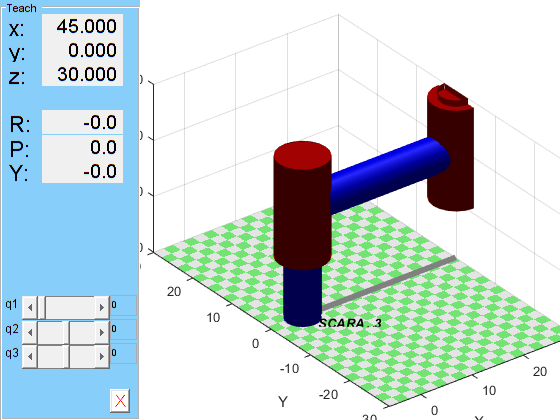

Scara_V3.plot([0 0 0], 'workspace', [-5 30 -30 30 0 30])
Scara_V3.teach


Af = ([5,pi/2,pi/2]); 